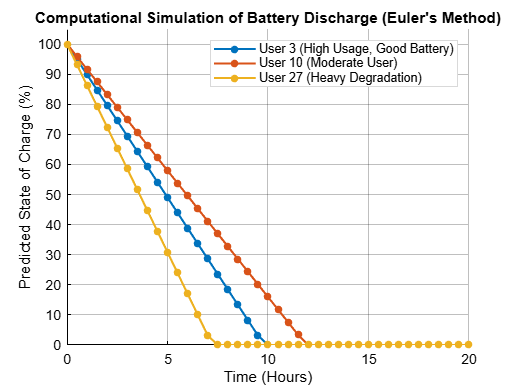

% Battery Life Prediction for Mobile Devices Using Numerical Approximation
% Hybrid Numerical Prediction Algorithm (Regression + Euler + Interpolation)

clc; clear; close all;

%% --- Step 1: Numeric survey data for 35 users ---
survey_data = [
7, 1, 3582, 2, 5, 0, 40, 6;   7, 3, 5000, 2, 2, 1, 5, 6;    9, 1, 5000, 1, 2, 1, 20, 15;
4, 3, 4500, 2, 5, 0, 60, 10;  9, 3, 5000, 2, 5, 1, 5, 6;    7, 3, 3227, 2, 3, 1, 20, 6;
7, 0, 6000, 1, 5, 1, 20, 15;  7, 3, 2942, 2, 2, 1, 20, 6;   9, 1, 3349, 1, 4, 1, 40, 15;
9, 3, 5000, 2, 4, 0, 20, 6;   9, 3, 3110, 2, 2, 1, 20, 6;   9, 1, 5000, 2, 5, 1, 20, 6;
7, 3, 3110, 2, 1, 1, 20, 6;   7, 0, 3110, 1, 2, 0, 20, 10;  7, 0, 5000, 1, 2, 0, 60, 10;
9, 3, 4352, 2, 3, 1, 5, 10;   7, 1, 3000, 2, 3, 1, 5, 6;    7, 3, 3110, 2, 4, 1, 60, 6;
7, 3, 3227, 2, 2, 1, 5, 6;    7, 1, 5160, 1, 3, 0, 5, 6;    7, 3, 5000, 2, 4, 1, 20, 15;
9, 1, 3279, 2, 2, 1, 20, 6;   9, 3, 3110, 2, 5, 1, 20, 6;   9, 3, 5000, 2, 3, 1, 20, 10;
9, 3, 5000, 2, 5, 1, 20, 10;  7, 3, 2815, 2, 4, 1, 20, 6;   4, 0, 5000, 1, 3, 0, 60, 10;
9, 0, 5160, 1, 2, 0, 20, 10;  9, 3, 2942, 2, 2, 1, 20, 6;   4, 0, 4674, 1, 3, 1, 20, 10;
9, 1, 5000, 2, 4, 0, 20, 15;  9, 3, 3227, 2, 3, 1, 60, 10;  4, 3, 4000, 1, 1, 0, 20, 6;
9, 3, 6000, 2, 2, 1, 20, 6;   7, 1, 4565, 2, 2, 1, 20, 6
];

X_base = survey_data(:,1:6);
num_users = size(X_base,1);

%% --- Step 2: Calculate TRUE Physical Battery Life for Training ---
Usage_Hours = survey_data(:,1);
End_of_Day_Pct = survey_data(:,7);

True_Discharge_Rate = (100 - End_of_Day_Pct) ./ Usage_Hours;
True_Battery_Life = 100 ./ True_Discharge_Rate; 
Y_target = True_Battery_Life; 

%% --- Step 3: Fit Advanced Regression Model ---
DeviceAge = X_base(:, 2);
ChargeFreq = X_base(:, 4);
BatteryWearFactor = DeviceAge .* ChargeFreq;
X_advanced = [X_base, BatteryWearFactor];

mdl = fitlm(X_advanced, Y_target, 'RobustOpts', 'on'); 

%% --- Step 4: Define Time Parameters for Euler's Method ---
h = 0.5;                % Discrete time step (30 minutes)
time_grid = 0:h:24;     % Simulate up to 24 hours
num_steps = length(time_grid);

%% --- Step 5: Setup Results Table ---
BatteryTable = table('Size',[num_users,10], ...
    'VariableTypes', repmat({'double'}, 1, 10), ...
    'VariableNames',{'User','PredTotalLife','DischargeRate_r','Battery6h','Interpolated_6_5h','Battery7h','Battery8h','ActualEndOfDayPct','EulerPredAtEndOfDay','ErrorMargin_Pct'});

%% --- Step 6: Compute predictions using Euler's Method ---
for i = 1:num_users
    user_vars = X_base(i,:);
    actual_usage_hrs = Usage_Hours(i);
    actual_end_pct = End_of_Day_Pct(i);
    
    user_wear_factor = user_vars(2) * user_vars(4);
    user_vars_advanced = [user_vars, user_wear_factor];
    
    T_pred = predict(mdl, user_vars_advanced);
    T_pred = max(3, min(T_pred, 48)); 
    r = 100 / T_pred;
    
    B = zeros(1, num_steps);
    B(1) = 100; 
    
    for n = 1:(num_steps-1)
        B(n+1) = B(n) - (r * h);
        if B(n+1) < 0, B(n+1) = 0; end
    end
    
    B_6h = B(time_grid == 6);
    B_7h = B(time_grid == 7);
    B_8h = B(time_grid == 8);
    
    % Linear Interpolation at 6.5 hours
    B_6_5h = B_6h + ((B_7h - B_6h) / (7 - 6)) * (6.5 - 6);
    if B_6_5h < 0, B_6_5h = 0; end
    
    Euler_Pred_At_Usage = 100 - (r * actual_usage_hrs);
    if Euler_Pred_At_Usage < 0, Euler_Pred_At_Usage = 0; end
    
    BatteryTable.User(i) = i;
    BatteryTable.PredTotalLife(i) = round(T_pred, 2);
    BatteryTable.DischargeRate_r(i) = round(r, 2);
    BatteryTable.Battery6h(i) = round(B_6h, 1);
    BatteryTable.Interpolated_6_5h(i) = round(B_6_5h, 1);
    BatteryTable.Battery7h(i) = round(B_7h, 1);
    BatteryTable.Battery8h(i) = round(B_8h, 1);
    BatteryTable.ActualEndOfDayPct(i) = actual_end_pct; 
    BatteryTable.EulerPredAtEndOfDay(i) = round(Euler_Pred_At_Usage, 1);
    BatteryTable.ErrorMargin_Pct(i) = round(abs(Euler_Pred_At_Usage - actual_end_pct), 2);
end

%% --- EXTRA: Generate a Graph ---
% Set the figure background to crisp white ('w') for the academic paper
figure('Name', 'Euler''s Method Battery Simulation', 'Color', 'w');
set(gcf, 'Renderer', 'painters'); 
hold on; grid on;

users_to_plot = [3, 10, 27]; 
colors = {'#0072BD', '#D95319', '#EDB120'};

for k = 1:3
    u_idx = users_to_plot(k);
    T_p = BatteryTable.PredTotalLife(u_idx);
    r_p = 100 / T_p;
    
    B_plot = zeros(1, num_steps);
    B_plot(1) = 100;
    for n = 1:(num_steps-1)
        B_plot(n+1) = max(0, B_plot(n) - (r_p * h));
    end
    
    plot(time_grid, B_plot, '-o', 'Color', colors{k}, 'LineWidth', 1.5, ...
        'MarkerSize', 4, 'MarkerFaceColor', colors{k});
end

% Set Title and Axis Labels to solid BLACK ('k')
title('Computational Simulation of Battery Discharge (Euler''s Method)', 'Color', 'k');
xlabel('Time (Hours)', 'Color', 'k');
ylabel('Predicted State of Charge (%)', 'Color', 'k');

% Set Legend text to solid BLACK ('k') and background to WHITE ('w')
lgd = legend('User 3 (High Usage, Good Battery)', 'User 10 (Moderate User)', 'User 27 (Heavy Degradation)', 'Location', 'northeast');
lgd.TextColor = 'k';
lgd.Color = 'w'; 

xlim([0 20]);
ylim([0 105]);

% Set the axes tick marks, numbers, and grid to standard black
ax = gca;
ax.XColor = 'k';
ax.YColor = 'k';
ax.Color = 'w'; % Sets the inner graph background to white

hold off;

% Save the high-quality image for your paper
exportgraphics(gcf, 'BatterySimulation.png', 'Resolution', 300);